# Deploy an Inference Model to an NVIDIA Jetson TX1

## Step 1: Install Prerequisite Products

To deploy MATLAB Code to an NVIDIA Jetson we will use GPU Coder to convert MATLAB into optimized CUDA code. To convert the code, a few prerequsite MathWorks and third-party packages listed below need to be installed:

#### MATLAB Pre-requisites: 

- MATLAB® (required)

- MATLAB Coder™ (required)

- Parallel Computing Toolbox™ (required)

- Deep Learning Toolbox™ (required for deep learning)

- [GPU Coder Interface for Deep Learning Libraries](https://www.mathworks.com/matlabcentral/fileexchange/68642-gpu-coder-interface-for-deep-learning-libraries?s_tid=FX_rc3_behav) (required for deep learning)

- [GPU Coder Support Package for NVIDIA GPU's](https://www.mathworks.com/matlabcentral/fileexchange/68644-gpu-coder-support-package-for-nvidia-gpus) (required to deploy code to NVIDIA GPUs)

- Image Processing Toolbox™ (recommended)

- Computer Vision Toolbox™ (recommended)

- Embedded Coder® (recommended)

- Simulink® (recommended)

#### Third-Party Products:

***On the Embedded Device (Jetson)***

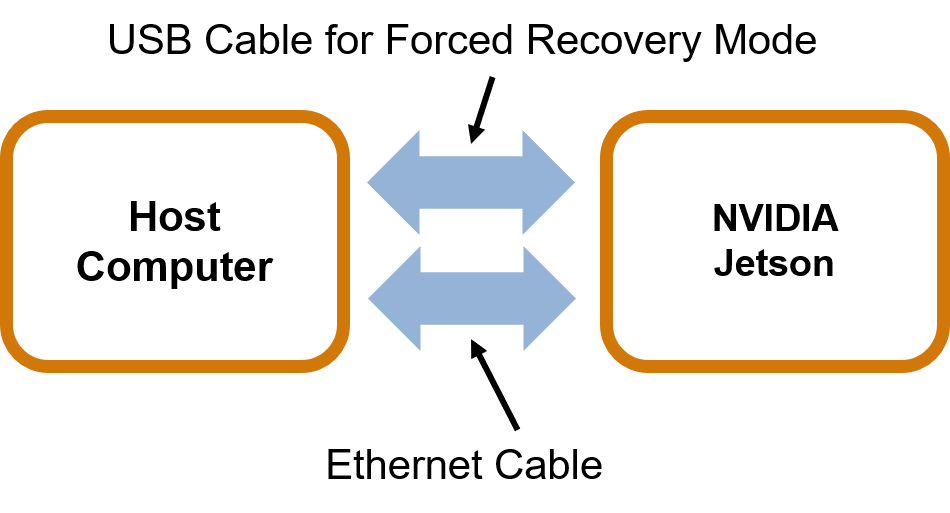

***Fig. 1: Jetson Setup Schematic***

- **Install JetPack on the NVIDIA Jetson:** To flash the NVIDIA Jetson with JetPack, which installs the OS, and the required libraries for deep learning including TensorRT, cuDNN, CUDA Toolkit, OpenCV etc, you will need a linux machine or a linux virtual machine on windows as the host machine. If using a virtual machine ensure sufficient memory allocation for the JetPack files. The JetPack installation folder is about 15 GB. Follow the instructions on this page, choose the NVIDIA SDK Manager Option if you are using a Jetson : [https://docs.nvidia.com/jetpack-l4t/2_1/content/developertools/mobile/jetpack/jetpack_l4t/2.0/jetpack_l4t_install.htm](https://docs.nvidia.com/jetpack-l4t/2_1/content/developertools/mobile/jetpack/jetpack_l4t/2.0/jetpack_l4t_install.htm) 

- **Install the Simple DirectMedia Layer  (SDL v1.2) library:** Open a Terminal on the Jetson and run the following commands

`        $ sudo apt-get install libsdl1.2debian`

`        $ sudo apt-get install libsdl1.2-dev`

- **Environment Variables on NVIDIA Jetson:** Ensure the following environment variables are set on the Jetson by adding the following  `export` command at the very beginning of the `$HOME/.bashrc` file for bash profiles. In a terminal use `sudo gedit $HOME/.bashrc `to open the file and add the following lines of code at the beginning.

            ` export PATH=/usr/local/cuda/bin:$PATH`

`       export LD_LIBRARY_PATH=/usr/local/cuda/lib64:$LD_LIBRARY_PATH`

***On the MATLAB Host***

Once you have installed JetPack on the NVIDIA jetson following the steps in the link above, a few third party libraries need to be installed on the computer running MATLAB. The computer running MATLAB could be Linux-based or Windows-based. For the rest of this example we will use a Windows machine. Install all the packages listed below:

- [C/C++ Compiler](https://www.mathworks.com/support/requirements/supported-compilers.html):** Microsoft Visual Studio 2013, Microsoft Visual Studio 2015, Microsoft Visual Studio 2017** can be used for **Windows **if using CUDA toolkit v10.0, for v10.1, **Microsoft Visual Studio 2019 **must be used **. **For **Linux **use **GCC C/C++ compiler 6.3.x**. 

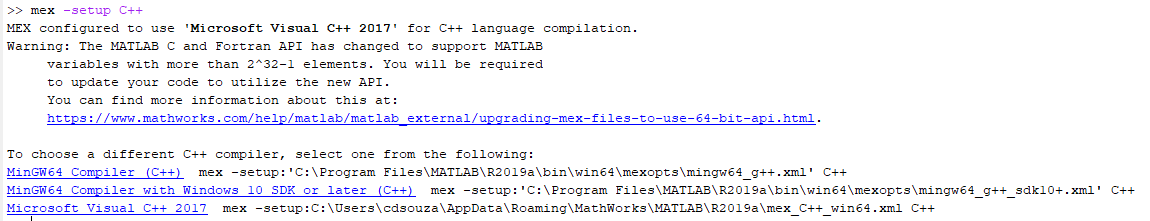

Run the code below to check the compiler setup

mex -setup C++

MEX configured to use 'Microsoft Visual C++ 2019' for C++ language compilation.

To choose a different C++ compiler, select one from the following:
Microsoft Visual C++ 2015  mex -setup:'C:\Program Files\MATLAB\R2019b\bin\win64\mexopts\msvcpp2015.xml' C++
Microsoft Visual C++ 2019  mex -setup:C:\Users\Visitor\AppData\Roaming\MathWorks\MATLAB\R2019b\mex_C++_win64.xml C++


- [CUDA Toolkit and driver](https://developer.nvidia.com/cuda-toolkit-archive) : GPU Coder has been tested with CUDA toolkit v10.0. The default installation comes with the `nvcc` compiler, `cuFFT`, `cuBLAS`, `cuSOLVER`, and Thrust libraries

- [CUDA Deep Neural Network library (cuDNN)](https://developer.nvidia.com/cudnn): The NVIDIA CUDA® Deep Neural Network library (cuDNN) is a GPU-accelerated library of primitives for deep neural networks. v7 or higher. Download the files and run the installer.

- [NVIDIA TensorRT](https://developer.nvidia.com/tensorrt): High Performance deep learning inference optimizer and runtime library, v6 and later. For R2019b and later GPU Coder supports TensorRT for CUDA Code generation from a Windows Machine.

- [OpenCV Libraries](https://opencv.org/releases/): Open Source Computer Vision Library ([OpenCV](https://opencv.org/)), v3.1.0 is required for deep learning examples. The `OpenCV` library that ships with Computer Vision Toolbox does not have all the required libraries and the [OpenCV](https://opencv.org/) installer does not install them. Therefore, you must download the `OpenCV` source and build the libraries

- CUDA toolkit for ARM® and [Linaro GCC 4.9](https://releases.linaro.org/components/toolchain/binaries/4.9-2016.02/aarch64-linux-gnu/) toolchain for the TX1 and TX2. Use the `gcc-linaro-4.9-2016.02-x86_64_aarch64-linux-gnu` release tarball.

Once all the third-party software libraries have been downloaded and installed, set up the environment variables so MATLAB can locate the necessary libraries, compilers and tools to generate CUDA code. **These environment variables will delete themselves everytime you restart MATLAB. To overcome this, you can add the code below to a startup script, edit as apporipriate for your machine**. Click this link to learn more : [https://www.mathworks.com/help/releases/R2019a/gpucoder/gs/setting-up-the-toolchain.html](https://www.mathworks.com/help/releases/R2019a/gpucoder/gs/setting-up-the-toolchain.html) 

% setenv('CUDA_PATH',fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","v10.0"))
% setenv('NVIDIA_CUDNN',fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","cuDNN"));
% setenv('NVIDIA_TENSORRT', fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","TensorRT"))
% setenv('OPENCV_DIR',fullfile("C:","Program Files","opencv","build"));
% setenv('PATH', ... 
%     [fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','v10.0','bin') ';' ...
%     fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','cuDNN','bin') ';'...
%     fullfile('C:','Program Files','opencv','build','x64','vc15','bin') ';'...
%     fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','TensorRT','lib') ';'...
%     getenv('PATH')]);

setenv('CUDA_PATH',fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","v10.1"))
setenv('NVIDIA_CUDNN',fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","cuDNN"));
setenv('NVIDIA_TENSORRT', fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","TensorRT"))
setenv('OPENCV_DIR',fullfile("C:","Program Files","opencv","build"));
setenv('PATH', ... 
    [fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','v10.1','bin') ';' ...
    fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','cuDNN','bin') ';'...
    fullfile('C:','Program Files','opencv','build','x64','vc15','bin') ';'...
    fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','TensorRT','lib') ';'...
    getenv('PATH')]);

## Step 2: Connect to Jetson and Verify Setup

Setup the Jetson Object in MATLAB

%ipaddress = '18.125.5.100'; % This is specific to your jetson, use ifconfig to find the ipaddress or set a static ip for the jetson 
% ipaddress = '127.0.0.1';
ipaddress = '169.254.215.90'

ipaddress = '169.254.215.90'

username = 'arbot';
password = 'arbot';
hwobj = jetson(ipaddress, username, password);

Checking for CUDA availability on the Target...
Checking for 'nvcc' in the target system path...
Checking for cuDNN library availability on the Target...
Checking for TensorRT library availability on the Target...
Checking for prerequisite libraries is complete.
Gathering hardware details...
Gathering hardware details is complete.
 Board name        : NVIDIA Jetson TX2
 CUDA Version      : 10.0
 cuDNN Version     : 7.6
 TensorRT Version  : 6.0
 Available Webcams : USB 2.0 Camera
 Available GPUs    : NVIDIA Tegra X2


To verify, if you have installed all the required support packages and if your system is ready for code generation run the following commands. This can also be done interactively using `coder.checkGpuInstallApp`

gpuEnvObj = coder.gpuEnvConfig('jetson');
gpuEnvObj.BasicCodegen = 1;
gpuEnvObj.BasicCodeexec = 1;
gpuEnvObj.DeepLibTarget = 'cudnn'; % either tensorrt or cudnn
gpuEnvObj.DeepCodeexec = 1;
gpuEnvObj.DeepCodegen = 1;
gpuEnvObj.HardwareObject = hwobj;
results = coder.checkGpuInstall(gpuEnvObj);

Compatible GPU           : PASSED 
CUDA Environment         : PASSED 
	Runtime   : PASSED 
	cuFFT     : PASSED 
	cuSOLVER  : PASSED 
	cuBLAS    : PASSED 
cuDNN Environment        : PASSED 
Basic Code Generation    : PASSED 
Basic Code Execution     : PASSED 
Deep Learning (cuDNN) Code Generation: PASSED 
Deep Learning (cuDNN) Code Execution: PASSED 


## Step 3: Prepare the MATLAB Code

To understand the limitations of generating low-level code from MATLAB follow the code generation tutorials here : [https://www.mathworks.com/videos/series/student-competition-code-generation-training.html](https://www.mathworks.com/videos/series/student-competition-code-generation-training.html)

Create a function with your algorithms as shown below

% edit roboSubPredict.mlx

## Step 4: Generate Code, SETUP

Set up the coder configurations

cfg = coder.gpuConfig('exe');
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.Hardware.BuildDir = '~/yolov2BuildTest';
cfg.GenerateExampleMain = 'GenerateCodeAndCompile'

## Generate Code Using CodeGen

Execute the code generation command using the configurations

% initialize ROS connection

% rosshutdown;
% ipaddress = '169.254.215.90'

cfg =     Description: 'class CodeConfig: C code generation configuration.'
    Name: 'CodeConfig'

-------------------------------- Report -------------------------------

                      GenerateReport: false
                        LaunchReport: false
                   ReportInfoVarName: ''
          ReportPotentialDifferences: true

------------------------------- Debugging -----------------------------

                       RuntimeChecks: false

---------------------------- Code Generation --------------------------

                  BuildConfiguration: 'Faster Runs'
              CustomToolchainOptions: [1x20 cell]
                 DataTypeReplacement: 'CBuiltIn'
                 FilePartitionMethod: 'MapMFileToCFile'
                         GenCodeOnly: false
                 GenerateExampleMain: 'GenerateCodeAndCompile'
                    GenerateMakefile: true
    HighlightPotentialRowMajorIssues: true
                   MultiInstanceCode: false
                   

% username = 'arbot';
% password = 'arbot';
% rosinit(ipaddress);
% myPub = rospublisher('/joint_angles_topic','joint_angles_message_pkg/JointAnglesTemplate');
% myMsg = rosmessage('joint_angles_message_pkg/JointAnglesTemplate');


codegen('-config ', cfg,'roboSubPredict', '-report');

## Step 5: Run Application on Jetson

Use the Jetson object to launch the application on the device

hwobj.runApplication('roboSubPredict');

Code generation successful: View report


## Clean-up

hwobj.killApplication('roboSubPredict');

### Launching the executable on the target...
Executable launched successfully with process ID 20946.
Displaying the simple runtime log for the executable...

Note: For the complete log, run the following command in the MATLAB command window:
system(hwobj,'cat /home/arbot/yolov2BuildTest/MATLAB_ws/R2019b/C/Users/Visitor/Desktop/MATLAB_Entire_Integration/roboSubPredict.log');


close all
clear
clc